# Lab 3

## Es 1

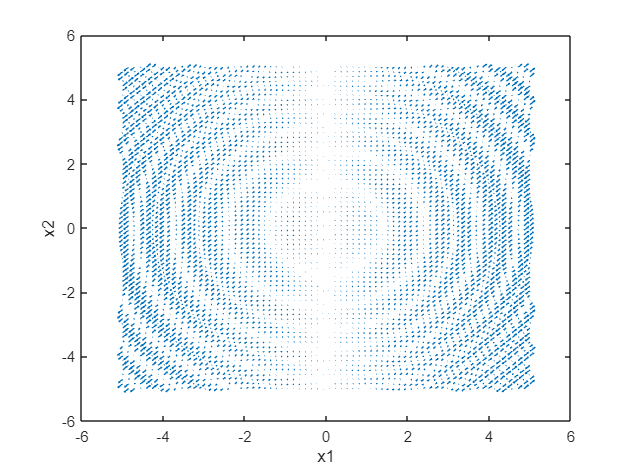

[X1 X2] = meshgrid(linspace(-5,5,70));
X1 = dlarray(X1(:));
X2 = dlarray(X2(:));
Y = dlarray(zeros(size(X1,1), 2));
DYDX = Y;
for i = 1:length(X1)
    [Y(i),DYDX(i,:)] = dlfeval(@funct,X1(i),X2(i));
end
quiver(extractdata(X1),extractdata(X2),extractdata(DYDX(:,1)),extractdata(DYDX(:,2)))
xlabel('x1')
ylabel('x2')

## Function

function [y,dydx] = funct(x1,x2)
    normSquared = x1^2 + x2^2;
    y = sin(pi/4 * normSquared);
    dydx = dlgradient(y, x1, x2);
end